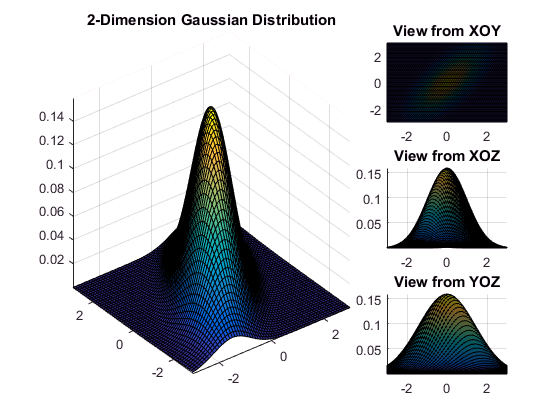

clc
clear
close all

Sigma=[1 1;1 2];% Covariance matrix
[X,Y]=meshgrid(-3:0.1:3,-3:0.1:3);%grid on XOY
p=mvnpdf([X(:) Y(:)],[0,0],Sigma);% produce a p.d.f (default mean is zero)
p=reshape(p,size(X)); % axis Z stands for the p.d.f
C = p; % Color is also changed by p.d.f

figure
% set(gcf,'Position',get(gcf,'Position').*[1 1 1.3 1])

subplot(3,3,[1 2 4 5 7 8])
surf(X,Y,p,C),axis tight,title('2-Dimension Gaussian Distribution')
subplot(3,3,3)
surf(X,Y,p,C),view(2),axis tight,title('View from XOY')
subplot(3,3,6)
surf(X,Y,p,C),view([0 0]),axis tight,title('View from XOZ')
subplot(3,3,9)
surf(X,Y,p,C),view([90 0]),axis tight,title('View from YOZ')

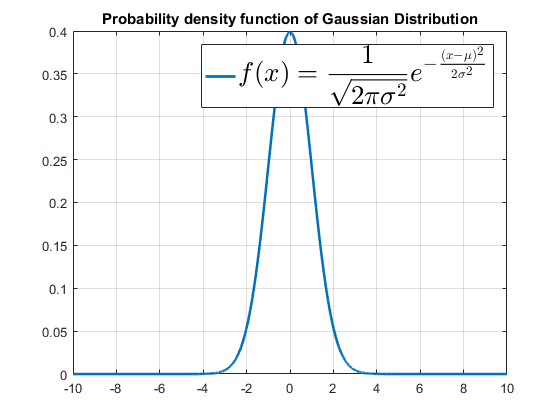

XX = linspace(-10,10,10000);
YY = normpdf(XX,0,1);
figure
plot(XX,YY,'LineWidth',2)
grid on
title1 = title('Probability density function of Gaussian Distribution');

legend1 = legend('$$f(x) = \frac{1}{\sqrt{2\pi \sigma^2}}e^{-\frac{(x-\mu)^2}{2\sigma^2}}$$');
set(legend1,'interpret','latex')
set(legend,'Fontsize',20);

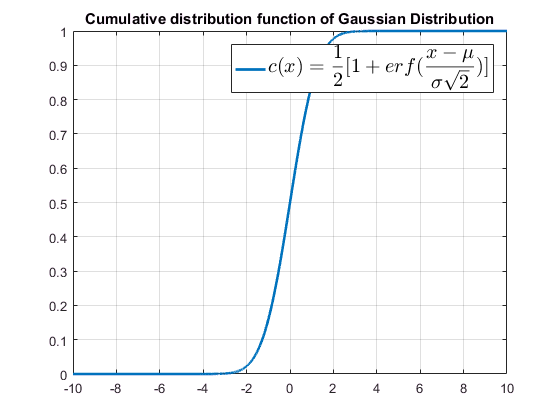


figure
ZZ = normcdf(XX,0,1);
plot(XX,ZZ,'LineWidth',2)
grid on
title2 = title('Cumulative distribution function of Gaussian Distribution');
legend2 = legend('$$c(x) = \frac{1}{2}[1 + erf(\frac{x - \mu}{\sigma\sqrt{2}})]$$');
set(legend2,'interpret','latex')
set(legend,'Fontsize',15);